range = 100;
rComm = 20;
rObs = 20;
agentNum = randi([5,15]);
iteration = 100;

D = randi([0,0], range, range);
for i = 1:iteration
    D = calcDensity(D, 1, range, 1); 
end
D

D =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   


%region = randi([1,100], 2, 2);
%D = calcDensity(D, region, 5);

% Initial points assignment
x=0+rand(1,D(1,1))*(1-0);
y=0+rand(1,D(1,1))*(1-0);

for i = 1:range
    for j = 1:range
        xN = range-((i-1)+rand(1,D(i,j))*(i-(i-1)));
        yN = (j-1)+rand(1,D(i,j))*(j-(j-1));
        x = horzcat(x, xN);
        y = horzcat(y, yN);
    end
end

% Bin the data:
pts = linspace(0, range, range);
N = histcounts2(x(:), y(:), pts, pts);

% Plot data:
scatter(y, x, 1, 'r.');
axis equal;
set(gca, 'XLim', pts([1 end]), 'YLim', pts([1 end]));

hold on;
agentPos = randi([20, 80], agentNum, 2)

agentPos =     38    60
    38    80
    44    29
    60    71
    25    77
    54    64
    53    74
    72    28


[commCells, adjMatrix] = communication(agentPos, rComm)

commCells = 1×8 cell array
    {3×1 double}    {4×1 double}    {[3]}    {3×1 double}    {2×1 double}    {4×1 double}    {4×1 double}    {[8]}


adjMatrix = 8×8 logical array
   1   0   0   0   0   1   0   0
   0   1   0   0   1   0   1   0
   0   0   1   0   0   0   0   0
   0   0   0   1   0   1   1   0
   0   1   0   0   1   0   0   0
   1   0   0   1   0   1   1   0
   0   1   0   1   0   1   1   0
   0   0   0   0   0   0   0   1


scatter(agentPos(:,1),agentPos(:,2),'b*');

agentPoints = assignAgentPoints(agentPos, commCells, range, 1, rObs);

size(agentPoints,1)

ans = 8

agentPoints

agentPoints = 8×1 cell array
    { 899×2 double}
    { 922×2 double}
    {1257×2 double}
    { 555×2 double}
    { 890×2 double}
    { 646×2 double}
    { 319×2 double}
    {1257×2 double}



for i = 1:agentNum
    scatter(agentPoints{i}(:,1), agentPoints{i}(:,2), 'g.')
end
mass = calcMass(agentPoints,D,1);

centroids = calcCentroids(agentPoints,mass,D,agentPos,1)

centroids =    37.3254   54.4683
   37.1687   83.8795
   46.2389   26.8250
   68.4336   72.4336
   26.5429   80.9429
   55.1871   55.8889
   54.8358   83.7612
   69.8618   20.7602


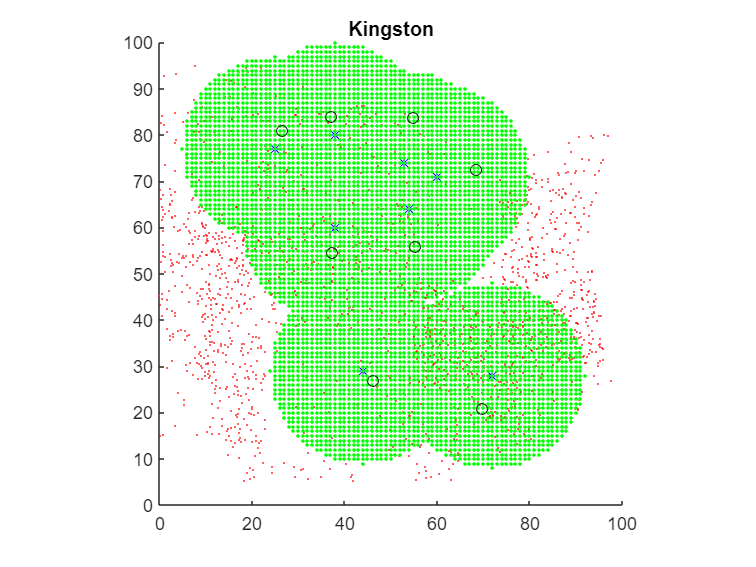

for i = 1:agentNum
    scatter(centroids(i,1), centroids(i,2), 'ko');
end

title('Kingston');

hold off;


calcMass(agentPoints, D, 1)

ans =    126
   166
   360
   339
    35
   171
   134
   246


calcCoverage(agentPoints,1,D,sum(sum(D)))

ans = 0.7541

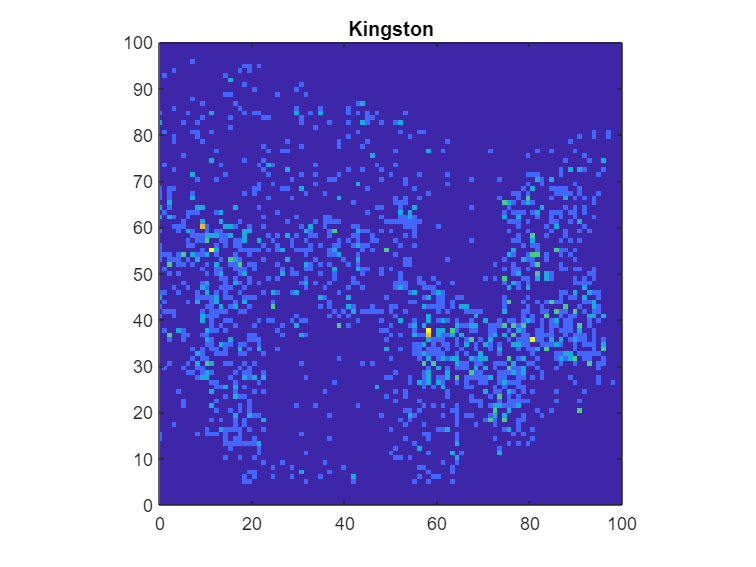


% Plot heatmap:
imagesc(pts, pts, N);
axis equal;
set(gca, 'XLim', pts([1 end]), 'YLim', pts([1 end]), 'YDir', 'normal');

title('Kingston');